# Building Heat Load Estimation

Copyright 2024 - 2025 The MathWorks, Inc.

In this workflow, you create a typical residential house and analyze the heat load on it for a several European cities. The analysis provides insight into the yearly energy requirements for heating or cooling and helps in selecting heat pumps.

## Create a Building

Create a house with an inclined roof. To learn more on how to create a typical house or a multi-storied building, see [Create Building Model with Solar Load](matlab:open('./CreateBuildingModelWithSolarLoad.mlx')). In this workflow, function `createSimpleHouseWithInclinedRoof` is used to create a south facing house with a roof height of 5-feet and larger roof inclination that points south in the Northern Hemisphere. The house has two levels and each floor has 6 rooms. For simplicity, the model removes the internal walls to represent a larger room, with 6 thermal masses, called parts.

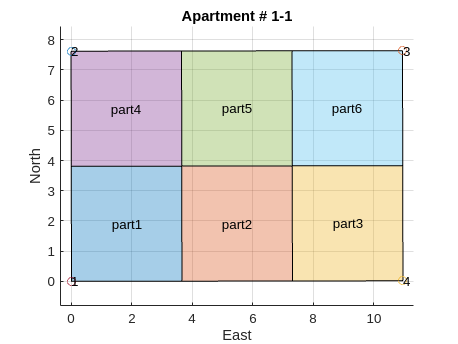

Use function addOpeningOnWallSection() to add windows or vent to the walls.
Adding windows on all 4 sides of the building
Inclined roof angles = 59 degrees and 12.8 degrees, respectively.


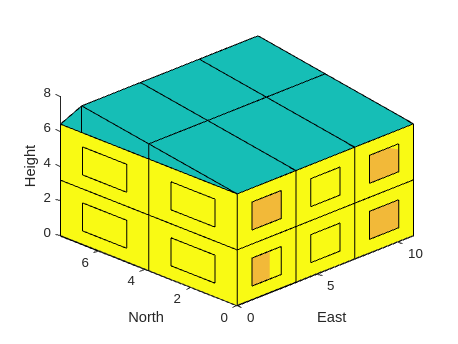

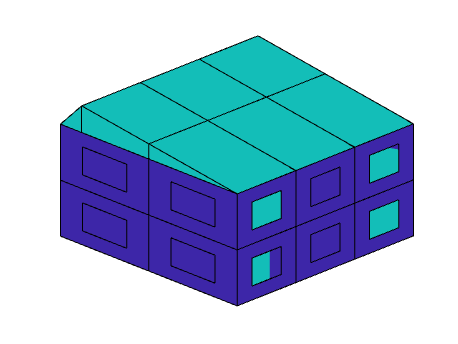

building = createSimpleHouseWithInclinedRoof(InclinationSide="Longer",...
                                             RoofHeight=simscape.Value(5,"ft"),...
                                             RoofTopFractionalDistance=0.88,...
                                             Tol=0.01,...
                                             Plot=true,...
                                             PlotViewDirection=[-1 -1 1]);

## Specify Building Parameters

Specify the start and end time for heat load calculations.

tStart = datetime(2024,1,1,1,0,0); % YYYY,MM,DD,HR,MM,SS
tEnd   = datetime(2024,12,31,1,0,0); % YYYY,MM,DD,HR,MM,SS

Specify the house occupancy per hour, in terms of number of people, during a day.

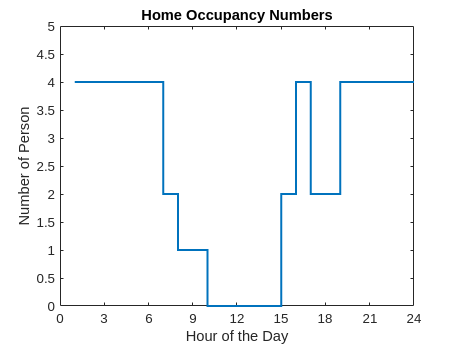

occupancyRate = set24HourRoomOccupancyNumber(OccupancyNumbers=[4 4 4 4 4 4 ... % 00:00 - 06:00 Hrs
                                                               2 1 1 0 0 0 ... % 06:00 - 12:00 Hrs
                                                               0 0 2 4 2 2 ... % 12:00 - 18:00 Hrs
                                                               4 4 4 4 4 4],...% 18:00 - 24:00 Hrs
                                                               Plot=true);

Load data for common building wall material.

matProp = load("BuildingWallMaterial.mat");

Initialize the building material properties for the walls, roof, floor, and windows. Specify the external wall as bricks, internal wall as clinker bricks, floor as concrete, and roof as wood. Window glass properties are kept to the default values.

tblMatProp = initializeBuildingMaterialProperties(DisplayData=true,...
    ExternalWallDensity=matProp.Material.Brick.Density,...
    ExternalWallHeatCapacity=matProp.Material.Brick.HeatCapacity,...
    ExternalWallThermalConductivity=matProp.Material.Brick.ThermalConductivity,...
    ExternalWallThickness=simscape.Value(0.3,"m"),...
    InternalWallDensity=matProp.Material.ClinkerBrick.Density,...
    InternalWallHeatCapacity=matProp.Material.ClinkerBrick.HeatCapacity,...
    InternalWallThermalConductivity=matProp.Material.ClinkerBrick.ThermalConductivity,...
    InternalWallThickness=simscape.Value(0.2,"m"),...
    FloorDensity=matProp.Material.Concrete.Density,...
    FloorHeatCapacity=matProp.Material.Concrete.HeatCapacity,...
    FloorThermalConductivity=matProp.Material.Concrete.ThermalConductivity,...
    FloorThickness=simscape.Value(0.3,"m"),...
    RoofDensity=matProp.Material.Wood.Density,...
    RoofHeatCapacity=matProp.Material.Wood.HeatCapacity,...
    RoofThermalConductivity=matProp.Material.Wood.ThermalConductivity,...
    RoofThickness=simscape.Value(0.25,"m"),...
    RoofAbsorptivity=simscape.Value(0.25,"1"));

*** You must not specify values marked as NaN in the table.
*** Block default values are provided where name-value-pair are not defined.
                                    Roof     Floor    ExternalWall    InternalWall    Window
                                    _____    _____    ____________    ____________    ______

    Absorptivity [-]                 0.25     NaN          0.6             NaN          0.4 
    Transmissivity [-]                NaN     NaN          NaN             NaN          0.2 
    Thickness [m]                    0.25     0.3          0.3             0.2         0.01 
    Density [kg/m^3]                   60    2000         1400             650         4000 
    Heat Capacity [J/kg-K]           2500    1100

Set the desired temperature for the house.

desiredSetPointTemperatureK = simscape.Value(293,"K");

Analyze the heating load for 3 European cities - Zurich, Stockholm, and Vienna.

analyzePreComputedResults = true;

Running the simulation for one year across three cities takes a few minutes. In the example here, the simulation has been run, results pre-computed and stored in `BuildingHeatLoadEstimationRes` MAT file for post-processing. Set the parameter `analyzePreComputedResults` to `false` to run the simulation again.

if analyzePreComputedResults
    load BuildingHeatLoadEstimationRes.mat
else
    placeOfInterest = ["Zurich","Stockholm","Vienna"];
    getTemperatureForFewCities;
    %
    for i = 1:length(placeOfInterest)
        
        % Find geographical coordinates for solar tracking.
        geoLocation = getGeoLocationForMajorCities(CityName=placeOfInterest(1,i));

        if ~isempty(geoLocation)
        
            % Load monthly average temperature of the place of interest, as
            % defined in the getTemperatureForFewCities.m file.
            monthlyTavgMat = monthlyTavg.(placeOfInterest(1,i));
            
            % Add solar load to building, for the entire modelling duration
            % specified by tStart and tEnd datetime values.
            [building3D,dateTimeVec] = addSolarLoadToBuilding(Building=building,...
                Location=geoLocation,StartTime=tStart,EndTime=tEnd);
            
            % Create vector data for average day and night time data, from
            % the monthly temperature data defined in monthlyTavgMat using
            % script getTemperatureForFewCities.m.
            [avgDayT,avgDayTvar,avgNightT,avgNightTvar] = ...
                getTemperatureFromYearlyData(DateTimeVec=dateTimeVec,...
                Tavg12MonthData=monthlyTavgMat,DeltaDegreesNightT=simscape.Value(3,"K"),...
                Plot=true,PlotName=placeOfInterest(1,i),Location=geoLocation,...
                PercentDayTimeTvar=1,PercentNightTimeTvar=1);

            % Initialize parameters for the building analysis. Building
            % physics related and operational information is stored in the
            % parameters physTable and opsParams, respectively.
            [physTable,opsParams] = initializeBuildingSimulationParameters(Building=building3D,...
                DateTimeVec=dateTimeVec,Location=geoLocation,GroundResistance=simscape.Value(100,"K/W"),...
                RoomTsetPoint=desiredSetPointTemperatureK,HeatLoadPerPerson=simscape.Value(50,"W"),...
                DayTemperature=avgDayT,DayTemperatureVar=avgDayTvar,...
                NightTemperature=avgNightT,NightTemperatureVar=avgNightTvar);
            
            [listOfRoomNames,listOfFloorLvls] = getAllRoomNameForBuilding(Building=building3D);
            
            % Apply 24hr room occupancy data to all rooms for all days
            % specified by the datetime vector, datetimeVec.
            physTable = apply24HrsDataForAllDaysToBuildingPhysics(Building=building3D,...
                Data=occupancyRate,DateTimeVec=dateTimeVec,ListOfFloorLevels=unique(listOfFloorLvls)',...
                ListOfRoomNames=unique(listOfRoomNames)',PhysicsParameter="Room Occupancy Level",...
                PhysicsTable=physTable);
            
            % Set the HVAC model to be "alwaysON". This would set HVAC
            % operation as ON at all times. Setting this name value pair to
            % "adaptive" would switch off HVAC, when there are no occupants
            % in a room.
            physTable = editHVACBasedOnRoomOccupancyBuildingPhysics(PhysicsTable=physTable,...
                HVAC="alwaysON");
            
            % Collate all building modelling data into one struct.
            bldgModelData = getParamsForSimscapeComponent(Building=building3D,...
                PhysicsTableData=physTable,OperationalData=opsParams);

            % Parameterize the model.
            mdl = setParametersForBuildingCustomComponent(Building=building3D,...
                BuildingNetworkData=bldgModelData,RoomModel="Thermal Requirements",...
                Duration=dateTimeVec,ExternalHTC=simscape.Value(50,"W/(K*m^2)"),...
                InternalHTC=simscape.Value(50,"W/(K*m^2)"),BuildingMaterial=tblMatProp);
            
            % Run the model.
            results = sim(mdl);
            
            % Save the analysis results.
            summary.(placeOfInterest(1,i)).results = results.simlog.Building.S.series.values;
            summary.(placeOfInterest(1,i)).bldgModelData = bldgModelData;
            summary.(placeOfInterest(1,i)).building = building3D;
            summary.(placeOfInterest(1,i)).dateTimeVector = dateTimeVec;
            summary.(placeOfInterest(1,i)).geoLocation = geoLocation;
            summary.(placeOfInterest(1,i)).tblMatProp = tblMatProp;
        else
            summary.(placeOfInterest(1,i)) = [];
        end
    end
end
clearvars -except summary

## Analyze Results

Plot the monthly average heating requriement for Zurich, Stockholm, and Vienna. 

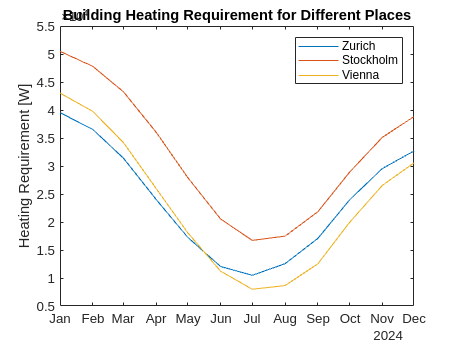

monthlyAveragedHeatingRequirement(ResultSummary=summary,PlotOption="Watt",PlotType="Heating Requirements");

This plot demonstrates the heating requirements for the same house at different locations. The methodology used in this example can be extended to evaluate the impact of building material properties and thickness.